# Cameras

We render the chess set scene through a camera with a lens . The output is the spectral irradiance at the sensor surface (the optical image).

This script  illustrates how to set the focal distance, and it reveals the depth of field for this double Gauss lens.

## Set up ISETCam

Also, make sure we have docker running.

ieInit;
if ~piDockerExists, piDockerConfig; end
if isempty(which('lensC'))
    error('You must add the isetlens repository to your path');
end

## Read the PBRT scene

% thisR = piRecipeDefault('scene name','chessset');
thisDB = isetdb;
sceneName = 'ChessSet';
thisScene = thisDB.contentFind('PBRTResources', 'name',sceneName);
thisR = piRead(thisScene,'docker',isetdocker);

[INFO]: Use a database scene: [/acorn/data/iset/PBRTResources/scene/ChessSet/ChessSet.pbrt].



% thisR = piRecipeDefault('scene name','ChessSet');
thisR.set('spatial resolution',512);

## Create a camera with a double Gauss lens

lensname    = 'dgauss.22deg.12.5mm.json';
doubleGauss = piCameraCreate('omni','lens file',lensname);

thisR.set('camera',doubleGauss);

The distance that will be in focus

thisR.set('focus distance',0.8);

## Change the camera position

Set the camera position a little higher than default.  That makes it easier to see the ruler on the chess board.

thisR.set('from',[0,0.18,-0.5]);

Rotate the camera down a bit.  The (x,y) axes for this scene surpise me.

piCameraRotate(thisR, 'x rot',-10);

Summarize the recipe information.  There is a lot for this scene.  But you can handle it.

thisR.summarize;


File information
-----------
Input:  /acorn/data/iset/PBRTResources/scene/ChessSet/ChessSet.pbrt
Output: /Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/ChessSet.pbrt

Renderer information
-----------
Rays per pixel 32
Bounces 5

Camera
-----------
Sub type:	omni
Lens file name:	/Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/dgauss.22deg.12.5mm.json
Aperture diameter (mm): 5.00
Focal distance (m):	0.80
Film distance (mm):	9.23
Film diagonal (mm):	10.0
Sample spacing (um):	13.8
Exposure time (s):	1.0000
FOV (deg):		58.0
Spatial samples:	512 512

Camera
-----------
Sub type:	omni
Lens file name:	/Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/dgauss.22deg.12.5mm.json
Aperture diameter (mm): 5.00
Focal distance (m):	0.80
Film distance (mm):	9.23
Film diagonal (mm):	10.0
Sample spacing (um):	13.8
Exposure time (s):	1.0000
FOV (deg):		58.0
Spatial samples:	512 512

Lookat parameters
-----------
from:	0.000 0.180 -0.500
to:	0.000 -0.102 0.466
up:	0.000 1.00

## Write and render

oi = piWRS(thisR,'render type','radiance','show',false);

[INFO] Updated: /Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/ChessSet.pbrt to /home/wandell/ISETRemoteRender/ChessSet/ChessSet.pbrt
[INFO] Updated: /Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/ChessSet_geometry.pbrt to /home/wandell/ISETRemoteRender/ChessSet/ChessSet_geometry.pbrt
[INFO] Updated: /Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/ChessSet_materials.pbrt to /home/wandell/ISETRemoteRender/ChessSet/ChessSet_materials.pbrt
[INFO] Entering directory: /Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/geometry
[INFO] Synchronization complete.
[INFO] Entering directory: /Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/lens
[INFO] Synchronization complete.
[INFO] Synchronization complete.
[INFO]:USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-wandell18778 sh -c " pbrt  --gpu  --outfile /home/wandell/ISETRemoteRender/ChessSet/renderings/ChessSet.exr /home/wandell/ISETRemoteRender/ChessSet/ChessSet.pbrt "
[INFO

oi = piAIdenoise(oi);

Folder already exists: /Users/wandell/Documents/MATLAB/iset3d-tiny/external/oidn-2.2.0.arm64.macos
Denoised in: 7.981


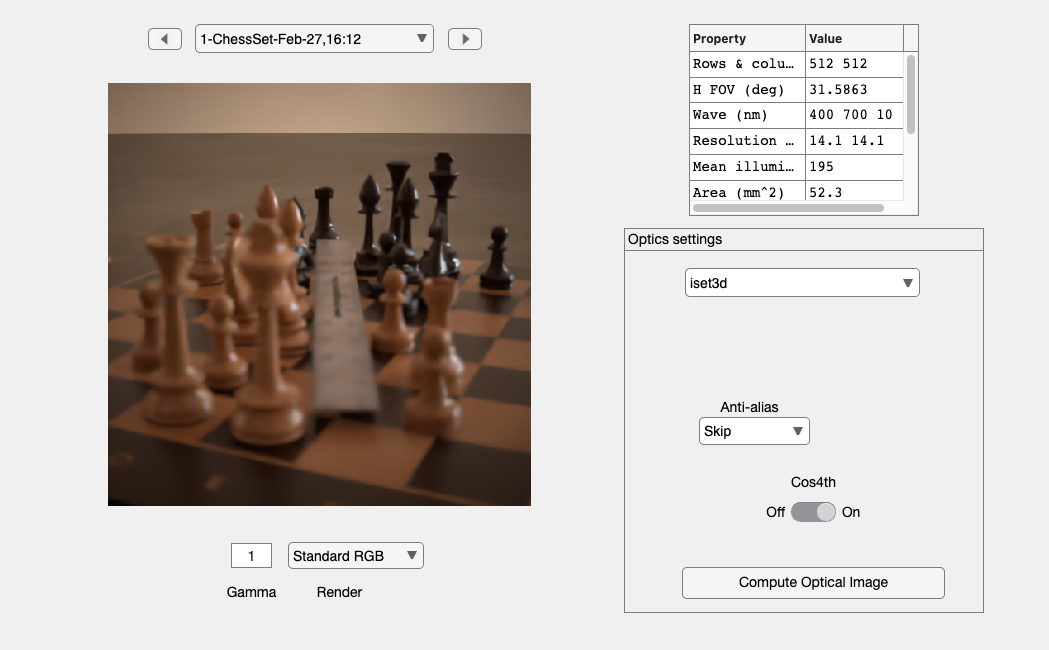

ans =   oiWindow_App with properties:

                      figure1: [1×1 Figure]
                     FileMenu: [1×1 Menu]
               menuFileLoadOI: [1×1 Menu]
               menuFileSaveOI: [1×1 Menu]
                menuSaveImage: [1×1 Menu]
              menuFileRefresh: [1×1 Menu]
                menuFileClose: [1×1 Menu]
                     EditMenu: [1×1 Menu]
                 menuEditName: [1×1 Menu]
               menuEditCreate: [1×1 Menu]
                   menuCopyOI: [1×1 Menu]
               menuEditDelete: [1×1 Menu]
           menuEditDeleteSome: [1×1 Menu]
                menuEditScale: [1×1 Menu]
             RemoveborderMenu: [1×1 Menu]
             menuEditFontSize: [1×1 Menu]
         menuEditClearMessage: [1×1 Menu]
               menuEditViewer: [1×1 Menu]
                     PlotMenu: [1×1 Menu]
               plotIrradiance: [1×1 Menu]
          menuPlotIrradEnergy: [1×1 Menu]
        

oiWindow(oi)

## Change the focus distance to 0.4m

thisR.set('focus distance',0.4);
oi = piWRS(thisR,'render type','radiance','show',false); 

[INFO] Updated: /Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/ChessSet.pbrt to /home/wandell/ISETRemoteRender/ChessSet/ChessSet.pbrt
[INFO] Updated: /Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/ChessSet_geometry.pbrt to /home/wandell/ISETRemoteRender/ChessSet/ChessSet_geometry.pbrt
[INFO] Updated: /Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/ChessSet_materials.pbrt to /home/wandell/ISETRemoteRender/ChessSet/ChessSet_materials.pbrt
[INFO] Entering directory: /Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/geometry
[INFO] Synchronization complete.
[INFO] Entering directory: /Users/wandell/Documents/MATLAB/iset3d-tiny/local/ChessSet/lens
[INFO] Synchronization complete.
[INFO] Synchronization complete.
[INFO]:USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-wandell18778 sh -c " pbrt  --gpu  --outfile /home/wandell/ISETRemoteRender/ChessSet/renderings/ChessSet.exr /home/wandell/ISETRemoteRender/ChessSet/ChessSet.pbrt "
[INFO

oi = piAIdenoise(oi);

Folder already exists: /Users/wandell/Documents/MATLAB/iset3d-tiny/external/oidn-2.2.0.arm64.macos


Denoised in: 7.802


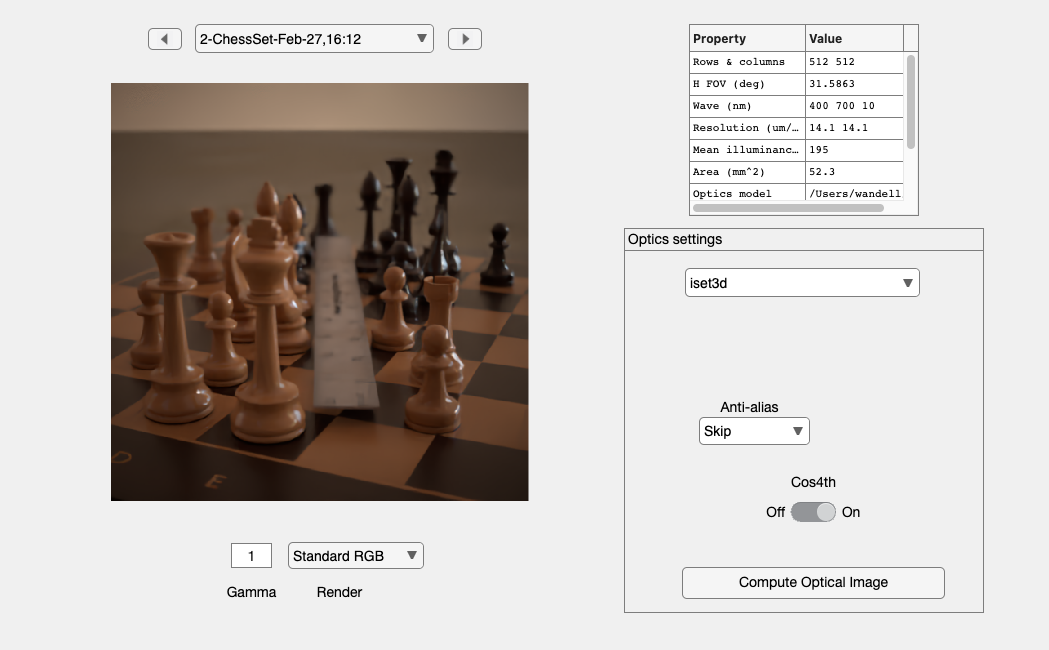

ans =   oiWindow_App with properties:

                      figure1: [1×1 Figure]
                     FileMenu: [1×1 Menu]
               menuFileLoadOI: [1×1 Menu]
               menuFileSaveOI: [1×1 Menu]
                menuSaveImage: [1×1 Menu]
              menuFileRefresh: [1×1 Menu]
                menuFileClose: [1×1 Menu]
                     EditMenu: [1×1 Menu]
                 menuEditName: [1×1 Menu]
               menuEditCreate: [1×1 Menu]
                   menuCopyOI: [1×1 Menu]
               menuEditDelete: [1×1 Menu]
           menuEditDeleteSome: [1×1 Menu]
                menuEditScale: [1×1 Menu]
             RemoveborderMenu: [1×1 Menu]
             menuEditFontSize: [1×1 Menu]
         menuEditClearMessage: [1×1 Menu]
               menuEditViewer: [1×1 Menu]
                     PlotMenu: [1×1 Menu]
               plotIrradiance: [1×1 Menu]
          menuPlotIrradEnergy: [1×1 Menu]
        

oiWindow(oi)